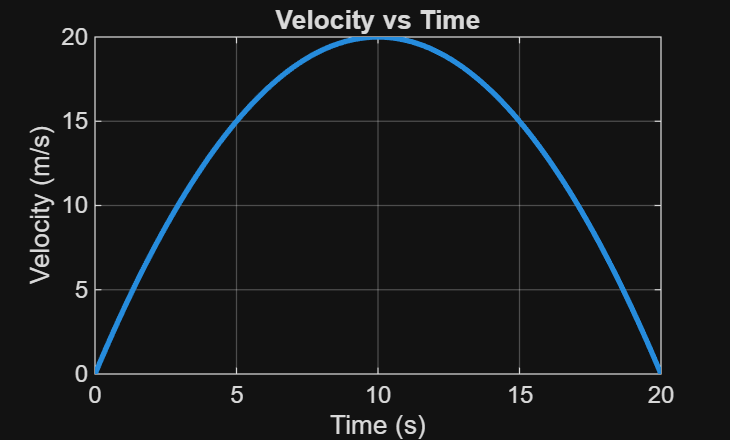

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 3 Project: Autonomous Cart Speed Profile 
% Instructor: Lynroy Grant 
% March 28, 2026 

clear; clc; close all; 
% ---------------------------- 

% Define time values 
t = 0:0.2:20;  

% Velocity function 
v = -0.2*(t - 10).^2 + 20; 
% ---------------------------- 

% Plot velocity vs time 
figure; 
plot(t, v, 'LineWidth', 2); 

title('Velocity vs Time'); 
xlabel('Time (s)'); 
ylabel('Velocity (m/s)'); 
grid on;  

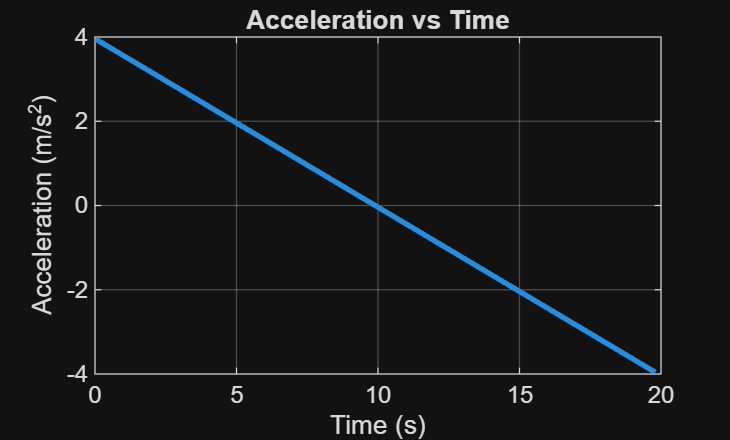

% ---------------------------- 

% Numerical acceleration (dv/dt) 
dt = 0.2; 
a = diff(v) / dt; 

% Adjust time for acceleration 
t_a = t(1:end-1); 
% ---------------------------- 

% Plot acceleration vs time 
figure; 
plot(t_a, a, 'LineWidth', 2); 

title('Acceleration vs Time'); 
xlabel('Time (s)'); 
ylabel('Acceleration (m/s^2)'); 
grid on; 

% ---------------------------- 

% Find maximum velocity 
[max_v, index] = max(v); 
t_max = t(index); 

fprintf('Maximum velocity: %.2f m/s at time %.2f seconds\n', max_v, t_max);   

Maximum velocity: 20.00 m/s at time 10.00 seconds


% ---------------------------- 

% Acceleration near max velocity 
accel_near_max = a(index); 
fprintf('Acceleration near max velocity: %.2f m/s^2\n', accel_near_max); 

Acceleration near max velocity: -0.04 m/s^2
